## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

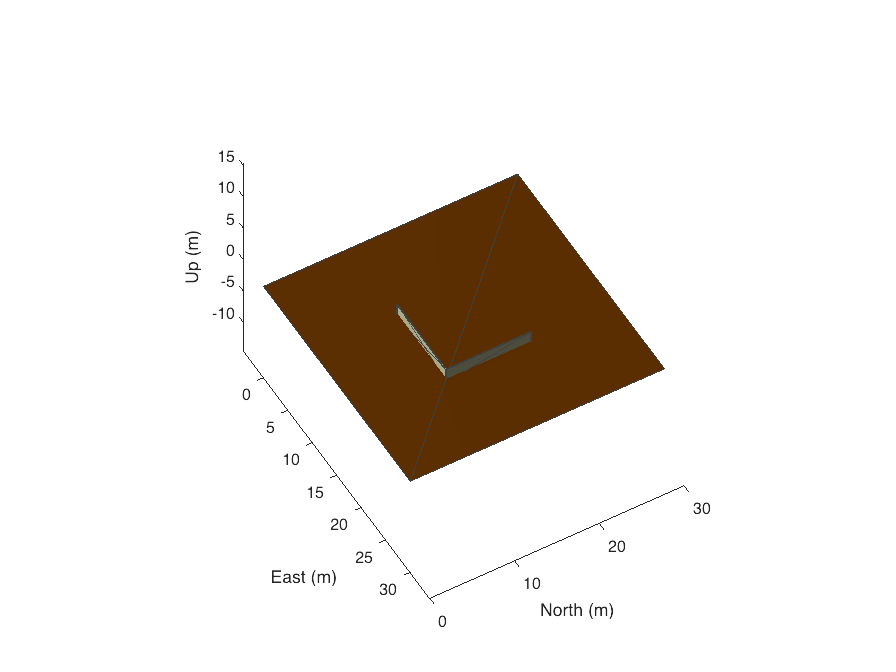

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
show3D(scenario);
lightangle(-45,30);
view(60,50);

## Load the points of interest

contents = load("experiments_comparison_points/experiment_1_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

rng(0) 
for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.DECENTRALISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});
end

Elapsed time is 2.409264 seconds.


ans =      9    17


ans =     13    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.514273 seconds.


ans =     29    15


ans =     25    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.653825 seconds.


ans =     19     3


ans =     29    15


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.096881 seconds.


ans =     26    29


ans =      9    17


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.144562 seconds.


ans =      9    17


ans =     13    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.057418 seconds.


ans =     25     5


ans =     20     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.568079 seconds.


ans =     25     5


ans =     26    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.342603 seconds.


ans =     25     5


ans =     19     3


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.921859 seconds.


ans =     29    15


ans =     25    28


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.664522 seconds.


ans =      9    17


ans =     29    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.692073 seconds.


ans =     29    29


ans =     24    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.749452 seconds.


ans =      4    28


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.334204 seconds.


ans =     26    29


ans =     24    29


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.803584 seconds.


ans =     24    29


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.554015 seconds.


ans =     26    29


ans =      5    30


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.671141 seconds.


ans =     25    28


ans =     25     5


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.228373 seconds.


ans =     25     5


ans =     29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.430136 seconds.


ans = 1×2
     4    28


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.311657 seconds.


ans = 1×2
    25    28


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.026881 seconds.


ans = 1×2
    29    29


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.841964 seconds.


ans = 1×2
    25    28


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.465120 seconds.


ans = 1×2
    19     3


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.716023 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.399504 seconds.


ans = 1×2
    20     2


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.326597 seconds.


ans = 1×2
    13    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.513196 seconds.


ans = 1×2
    25     5


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.473122 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.255388 seconds.


ans = 1×2
     5    30


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.331457 seconds.


ans = 1×2
    29    29


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.117242 seconds.


ans = 1×2
    25     5


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.936219 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.352997 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.679022 seconds.


ans = 1×2
    25    28


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.759240 seconds.


ans = 1×2
    29    29


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.185972 seconds.


ans = 1×2
    29    15


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.672169 seconds.


ans = 1×2
    13    28


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.520994 seconds.


ans = 1×2
    29    29


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.011002 seconds.


ans = 1×2
    25     5


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.529947 seconds.


ans = 1×2
    25     5


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.039408 seconds.


ans = 1×2
    25    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.311584 seconds.


ans = 1×2
    20     2


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.461178 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.753042 seconds.


ans = 1×2
    25    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.499790 seconds.


ans = 1×2
    29    15


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.241951 seconds.


ans = 1×2
    29    15


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.734342 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.834236 seconds.


ans = 1×2
    24    29


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.968793 seconds.


ans = 1×2
    24    29


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.525699 seconds.


ans = 1×2
    29    15


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.316423 seconds.


ans = 1×2
    13    28


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.676317 seconds.


ans = 1×2
    13    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.794746 seconds.


ans = 1×2
    29    29


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.702886 seconds.


ans = 1×2
    20     2


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.310425 seconds.


ans = 1×2
     4    28


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.959223 seconds.


ans = 1×2
    25    28


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.991093 seconds.


ans = 1×2
    20     2


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.480848 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.671042 seconds.


ans = 1×2
     5    30


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.515973 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.860991 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.740889 seconds.


ans = 1×2
    20     2


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.297271 seconds.


ans = 1×2
    25    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.708286 seconds.


ans = 1×2
    25     5


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.860027 seconds.


ans = 1×2
    25     5


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.759061 seconds.


ans = 1×2
    25     5


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.568607 seconds.


ans = 1×2
     4    28


ans = 1×2
    13    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.705740 seconds.


ans = 1×2
    29    29


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.907445 seconds.


ans = 1×2
    25    28


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.091668 seconds.


ans = 1×2
     4    28


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.090181 seconds.


ans = 1×2
    20     2


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.338785 seconds.


ans = 1×2
    20     2


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.723108 seconds.


ans = 1×2
     9    17


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.748078 seconds.


ans = 1×2
    13    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.142508 seconds.


ans = 1×2
    25    28


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.538811 seconds.


ans = 1×2
    29    15


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.036582 seconds.


ans = 1×2
    25    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.615299 seconds.


ans = 1×2
     9    17


ans = 1×2
    20     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.692715 seconds.


ans = 1×2
    25     5


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.209151 seconds.


ans = 1×2
    24    29


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.461719 seconds.


ans = 1×2
    25     5


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.417118 seconds.


ans = 1×2
    29    29


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.891640 seconds.


ans = 1×2
    19     3


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.300110 seconds.


ans = 1×2
    25     5


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.963879 seconds.


ans = 1×2
    13    28


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.754597 seconds.


ans = 1×2
    26    29


ans = 1×2
     9    17


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.875551 seconds.


ans = 1×2
     5    30


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.784923 seconds.


ans = 1×2
     4    28


ans = 1×2
    29    15


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.048854 seconds.


ans = 1×2
     9    17


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.284659 seconds.


ans = 1×2
    29    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.742986 seconds.


ans = 1×2
     5    30


ans = 1×2
    25    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.194668 seconds.


ans = 1×2
    25    28


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.070968 seconds.


ans = 1×2
     5    30


ans = 1×2
    25     5


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.429820 seconds.


ans = 1×2
    29    29


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.806951 seconds.


ans = 1×2
    26    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.424854 seconds.


ans = 1×2
    25     5


ans = 1×2
    24    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.109155 seconds.


ans = 1×2
    24    29


ans = 1×2
     5    30


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.325317 seconds.


ans = 1×2
    26    29


ans = 1×2
    19     3


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 4.092131 seconds.


ans = 1×2
     5    30


ans = 1×2
    29    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.937394 seconds.


ans = 1×2
    29    15


ans = 1×2
    26    29


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.107991 seconds.


ans = 1×2
    26    29


ans = 1×2
     4    28


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    2.4314
    2.5208
    2.6616
    3.1106
    2.1546
    3.0646
    2.5778
    3.3645
    3.9495
    3.6736


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    82    42
    78    64
    64    80
    66    72
    72    42
    74    94
    80    46
    58    96
   102    78
    86   104


smoothnessScores

smoothnessScores = 100×2
    9.4248    3.1416
   15.7080   12.5664
   10.9956   18.8496
   12.5664   14.1372
   10.9956    3.1416
   12.5664   12.5664
   12.5664    6.2832
    9.4248   12.5664
   15.7080    6.2832
   18.8496   12.5664


safetyScores

safetyScores = 100×2
     1     1
     6     6
     2     2
     8     8
     0     0
     0     0
    17    17
     1     1
     3     3
     9     9


save('experiments_comparison_results/experiment_1_new_decentralised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');